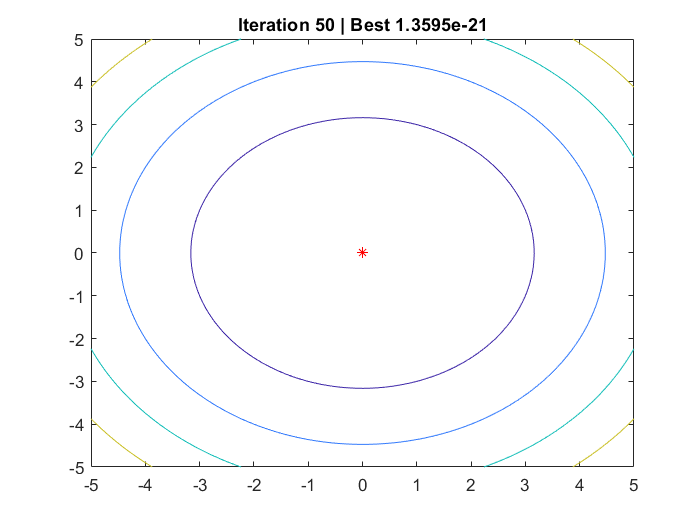

functionWrapper = @(X) (sphereFunction(X(1), X(2)));

config = PsoConfig();
config.bounds = [-5 5];
config.dimensions = 2;
config.particleCount = 50;
config.maxIterations = 50;
config.inertiaCoefficient = 0.5;
config.cognitiveCoefficient = 0.7;
config.socialCoefficient = 0.7;
config.dampingCoefficient = 0.99;

results = PSO(config, functionWrapper);
%bounds = [-1 1];
bounds = config.bounds;
graphWrapper = @(X1, X2) (sphereFunction(X1, X2));
for i=1:results.iterations
    fcontour(graphWrapper, 'fill', 'off', "XRange", bounds, "YRange", bounds, "LevelStep", 10)
    hold on
    plot(results.pointsHistory(:, 1, i), results.pointsHistory(:, 2, i), 'r*')
    hold on
    ylim(bounds)
    xlim(bounds)
    title(['Iteration ' num2str(i) ' | Best ' num2str(results.bestValueHistory(i))]);
    hold off;
    drawnow;
end